videosquence = 'foreman_cif-1.yuv';     % original yuv file
width = 352;                            % original yuv width
height = 288;                           % original yuv height
nframes = 10;                           % number of yuv frames
blockSize = 64;                          % 2, 8, 64
searchRange = 1;                        % can be set to 1, 4, 8
n = 1;                                  % can be set to 1, 2, 3
I_period = 4;                           % Different I-Period values: 1, 4, 10
QP_values = 0;                          % QP ranges for 8x8 and 16x16 blocks, {0:3:9, 1:3:10}, input one by one 
blocked_frame_cell_array = cell(1,300); % Storage for blocked frame, no meaningful use in algo., good visualizer

% extract Y, padding and blocking
A1_Q3_extract_YOnly(videosquence, height, width, nframes);

Y-only files Y!


[paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, blocked_frame_cell_array, nframes);

Y frame is split to blocks and padded as needed!


% Encoder----------------------------------------
% Start the timer
tic;    

% encoding process
[psnrValues] = A1_Q3_encoding(nframes, paddedWidth, paddedHeight, blockSize, height, width, searchRange, n, I_period, QP_values);

Dealing with frame 1, I-Period
Dealing with frame 2, F-Period
Dealing with frame 3, F-Period
Dealing with frame 4, F-Period
Dealing with frame 5, I-Period
Dealing with frame 6, F-Period
Dealing with frame 7, F-Period
Dealing with frame 8, F-Period
Dealing with frame 9, I-Period
Dealing with frame 10, F-Period



% Stop the timer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 1.63 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValues);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 49.38 dB


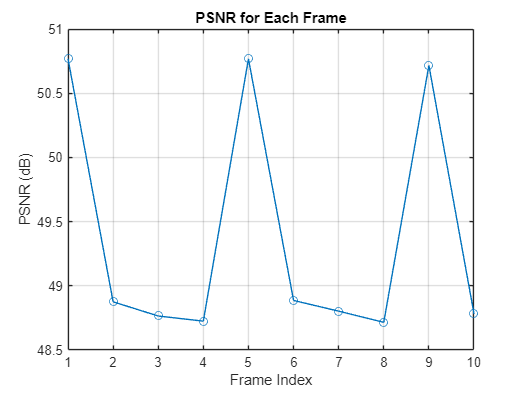


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;

% Decoder----------------------------------------
% Start the timer
tic;                                    

% decoding process
psnrValues_verify = A1_Q3_decoding(nframes, blockSize, paddedWidth, paddedHeight, height, width, QP_values);

% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.33 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 46.74 dB


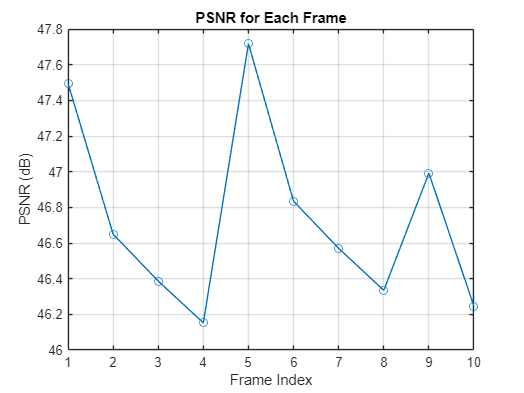


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;